# Newton method

syms q1 real 
syms q2 real
syms l1 l2 real
syms e

pd = [0.4 ; -0.3]

pd =     0.4000
   -0.3000


q0 = [0; -pi/2]

q0 =          0
   -1.5708


f_r = [ l1*cos(q1) + l2*cos(q1+q2); 
        l1*sin(q1) + l2*sin(q1+q2);]

$$f\_r = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$

f_r = subs(f_r, {l1, l2}, {0.5,0.4});

q_in = [q1 ; q2];
desired_point = pd;
initial_guess = q0;
max_iterations = 3;
max_cartesian_error = 0.0001;
min_joint_increment = 0.001;
max_closeness_singularity = 0.00001;

[q_out, guesses, cartesian_errors] = newton_method(q_in, desired_point, f_r, initial_guess, max_iterations, max_cartesian_error, min_joint_increment, max_closeness_singularity)

Non-redundant case, let's use the inverse
Finshed at iteration 3 because the error was lower than the specified amount.


q_out =     0.1796
   -1.9826


guesses =          0   -1.5708
    0.2000   -2.0208
    0.1796   -1.9826


cartesian_errors =     0.1414    0.0148    0.0001


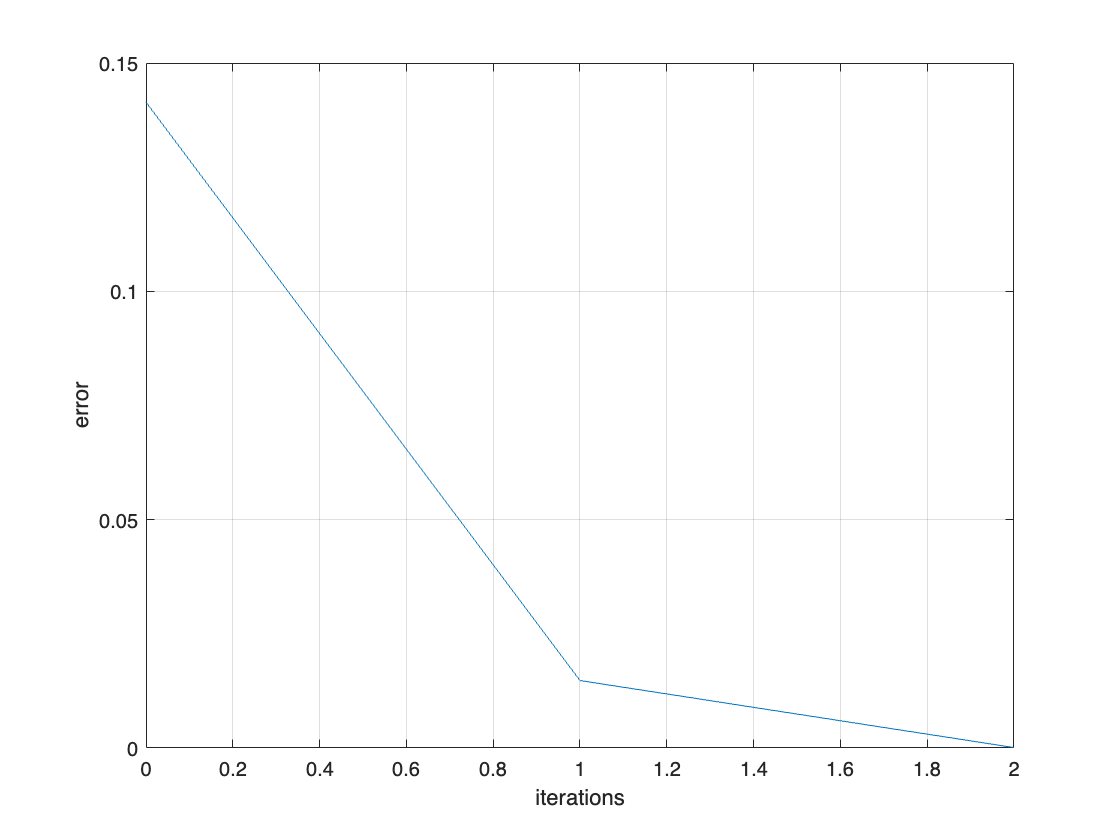

plot([0,1,2], cartesian_errors);
xlabel({'iterations'});
ylabel({'error'});
grid on;